# Tutorial 9 - Simulate a cylindrical cell

## Introduction

In this tutorial, we simulate a multilayer pouch cell. We use the same material property as in the other tutorials

jsonstruct_material = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

Next, we load and parse a json file where we have chosen some parameters for the multilayer pouch domain. Note that all the parameters are described in a json schema, see [Geometry.schema.json](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/JsonSchemas/Geometry.schema.json), even if the simplest way to proceed is to start with an example, in this case given by [4680-geometry.json](https://github.com/BattMoTeam/BattMo/blob/dev/Examples/JsonDataFiles/4680-geometry.json).

jsonfilename = 'Examples/JsonDataFiles/4680-geometry.json';
jsonstruct_geometry = parseBattmoJson(jsonfilename);

We change some parameters to get a smaller model and simulation time.

jsonstruct_geometry.Geometry.rOuter = jsonstruct_geometry.Geometry.rInner + 4*milli*meter;
jsonstruct_geometry.Geometry.nL     = 2;
jsonstruct_geometry.Geometry.nas    = 20;

We use [FlatJsonViewer.m](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/JsonUtils/FlatJsonViewer.m) to flatten the json structure and print it to screen.

fjv = flattenJson(jsonstruct_geometry);
fjv.print();

ans = 25x2 table
                          parameter name                          parameter value
    __________________________________________________________    _______________

    {'include_current_collectors'                            }    {[         1]} 
    {'Geometry.case'                                         }    {'jellyRoll' } 
    {'Geometry.rInner'                                       }    {[    0.0020]} 
    {'Geometry.rOuter'                                       }    {[    0.0060]} 
    {'Geometry.L'                                            }    {[    0.0700]} 
    {'Geometry.nas'                                          }    {[        20]} 
    {'Geometry.nL'                                           }    {[         2]} 
    {'NegativeElectrode.Coating.thickness'                   }    {[9.4000e-05]} 
    {'NegativeElectrode.Coating.N'                           }    {[         3]} 
    {'NegativeElectrode.Coating.SolidDiffusion.N'            }    {[         5]}

We load and parse the control protocol

jsonfilename = fullfile('Examples', 'jsondatafiles', 'cc_discharge_control.json');
jsonstruct_control = parseBattmoJson(jsonfilename);

We load and parse the simulation settings. This is optional. Typically, reasonable choices are made by default.

jsonfilename = fullfile('Examples', 'jsondatafiles', 'simulation_parameters.json');
jsonstruct_simparams = parseBattmoJson(jsonfilename);

Now, we can merge these parameter definitions into a single parameter set to obtain a jsonstruct that has all the input needed by the simulator.

jsonstruct = mergeJsonStructs({jsonstruct_geometry , ...
                               jsonstruct_material , ...
                               jsonstruct_control  , ...
                               jsonstruct_simparams}, 'warn', false);

## Setup the model for inspection

When we run the simulation using function [runBatteryJson.m](https://github.com/BattMoTeam/BattMo/blob/dev/Examples/JsonInput/runBatteryJson.m), the model is setup. In the case where we want to setup the model for inspection, prior to simulation, we can use the function [setupModelFromJson.m](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/JsonUtils/setupModelFromJson.m)

model = setupModelFromJson(jsonstruct);

We use the [plotBatteryGrid.m](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/Visualization/plotBatteryGrid.m) function to show the grid

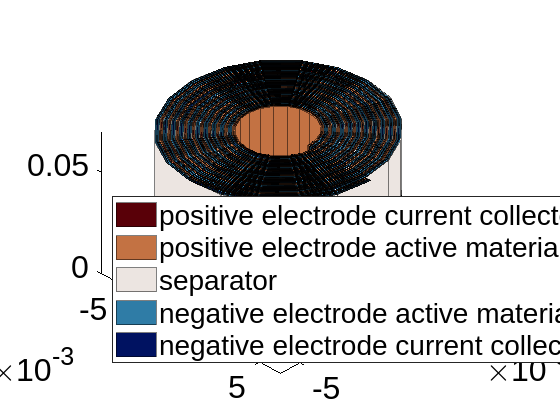

plotBatteryGrid(model)
% make the axis tight and set the camera viewing angle
axis tight
view(45,45)

## Run the simulation

output = runBatteryJson(jsonstruct);

## Visualize the Results

extract the time and voltage quantities

states = output.states;

time    = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);

We plot the discharge curves together in a new figure

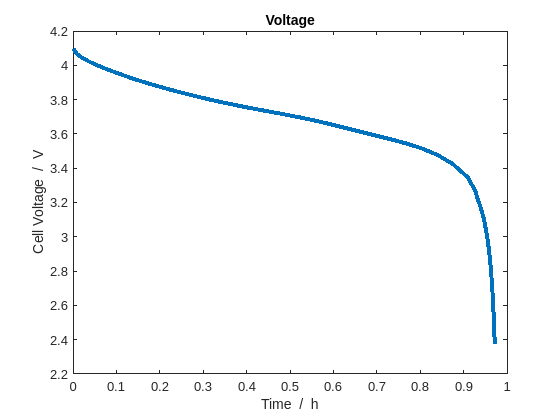

figure();
plot((time/hour), voltage, '-', 'linewidth', 3)
xlabel('Time  /  h')
ylabel('Cell Voltage  /  V')
title('Voltage');

For a given time step, we plot the concentration on the grid in the negative and positive electrodes.

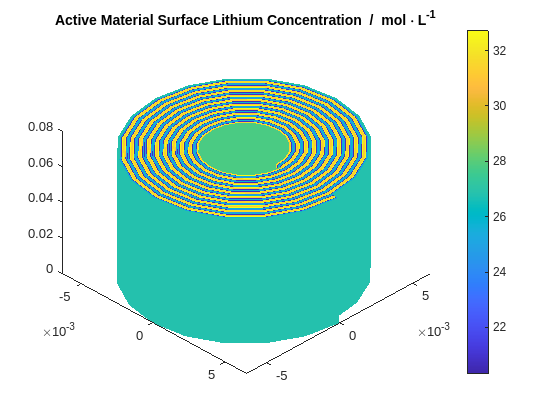

% Set the timestep we want to visualize
timestep = 20;

% get the state of the simulation at the given timestep
state = states{timestep};

% create a new figure
figure()

% plot the surface concentration of lithium in the negative electrode active material
plotCellData(model.NegativeElectrode.Coating.G, ...
             state.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre), ...
            'edgecolor', 'none');

% plot the surface concentration of lithium in the positive electrode active material
plotCellData(model.PositiveElectrode.Coating.G, ...
             state.PositiveElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre), ...
            'edgecolor', 'none')

title('Active Material Surface Lithium Concentration  /  mol \cdot L^{-1}');
% add a colorbar
colorbar()
view(45,45)